clear all
close all

addpath("Immagini\01_rumore25deg")
addpath("Immagini\02_rumore65deg")

noise = double(imread("noise25deg_1e-05s_1_X1.tif"));

image_1s = double(imread("noise25deg_1s_1_X1.tif"));
image_1s = image_1s-noise;

image_10s = double(imread("noise25deg_10s_3_X1.tif"));
image_10s = image_10s-noise;

image_60s = double(imread("noise25deg_60s_1_X1.tif"));
image_60s = image_60s-noise;

image_120s = double(imread("noise25deg_120s_1_X1.tif"));
image_120s = image_120s-noise;

image_180s = double(imread("noise25deg_180s_1_X1.tif"));
image_180s = image_180s-noise;

image_240s = double(imread("noise25deg_240s_1_X1.tif"));
image_240s = image_240s-noise;

image_300s = double(imread("noise25deg_300s_1_X1.tif"));
image_300s = image_300s-noise;

error_mean = [];
error_sigma = [];

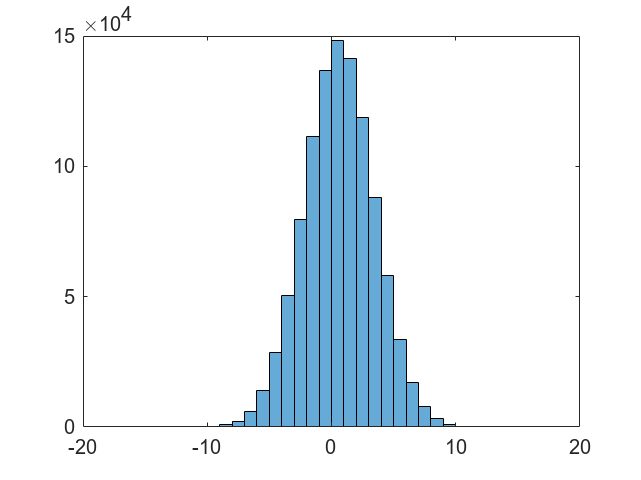

dist = histogram(image_1s, -2^15:1:2^15);
xlim([-20 20])

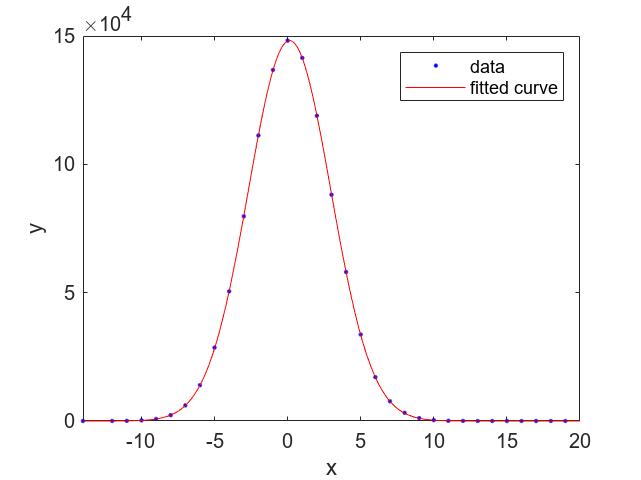


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss1');
plot(gaus,x,y)
xlim([-inf 20])


mean_1s = gaus.b1

mean_1s = 0.1340

sigma_1s = gaus.c1/sqrt(2)

sigma_1s = 2.8212


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0028

e_sigma = 0.0028

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

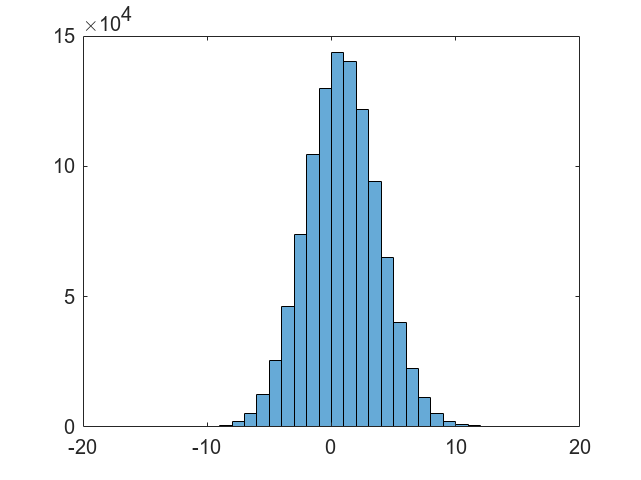

dist = histogram(image_10s, -2^15:1:2^15);
xlim([-20 20])

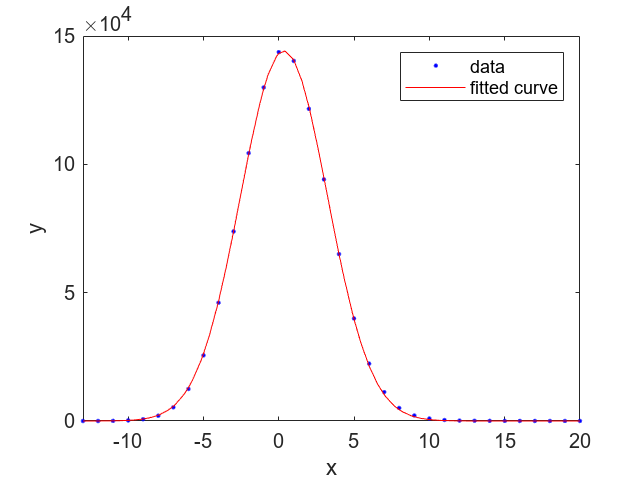


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss1');
plot(gaus,x,y)
xlim([-inf 20])


mean_10s = gaus.b1

mean_10s = 0.3459

sigma_10s = gaus.c1/sqrt(2)

sigma_10s = 2.8941


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0054

e_sigma = 0.0054

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

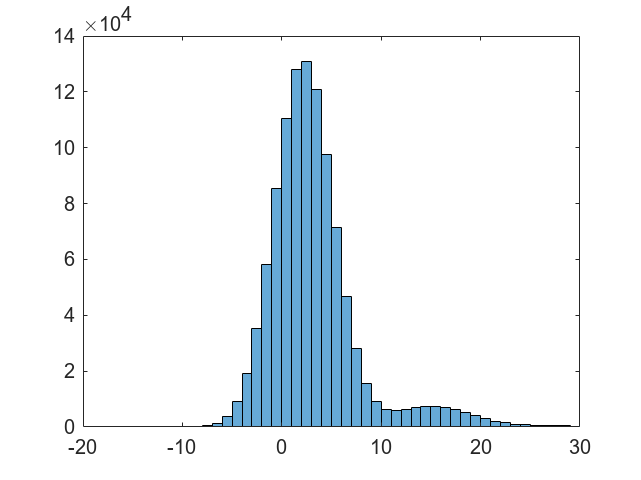

dist = histogram(image_60s, -2^15:1:2^15);
xlim([-20 30])

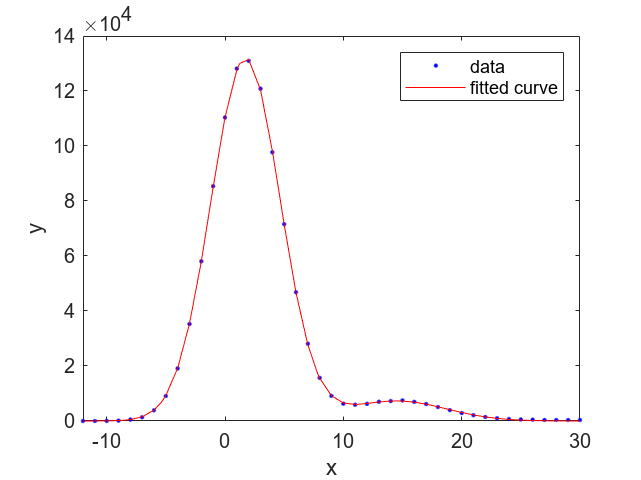


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2');
plot(gaus,x,y)
xlim([-inf 30])


mean_60s = gaus.b1

mean_60s = 1.7429

sigma_60s = gaus.c1/sqrt(2)

sigma_60s = 2.9260


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0025

e_sigma = 0.0026

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

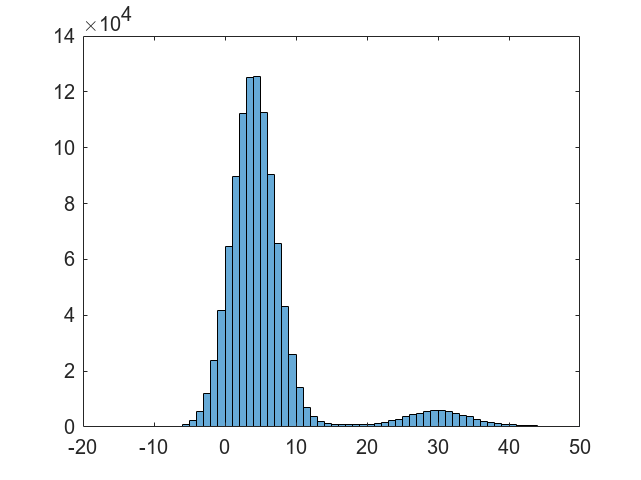

dist = histogram(image_120s, -2^15:1:2^15);
xlim([-20 50])

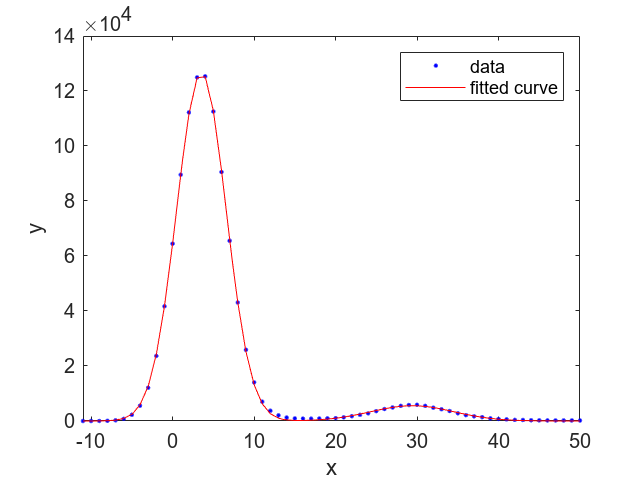


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2', 'Exclude', x>150);
plot(gaus,x,y)
xlim([-inf 50])


mean_120s = gaus.b1

mean_120s = 3.5320

sigma_120s = gaus.c1/sqrt(2)

sigma_120s = 3.0417


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0074

e_sigma = 0.0074

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

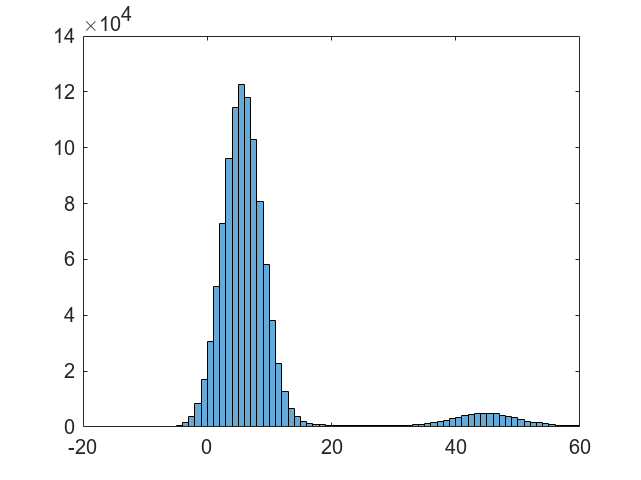

dist = histogram(image_180s, -2^15:1:2^15);
xlim([-20 60])

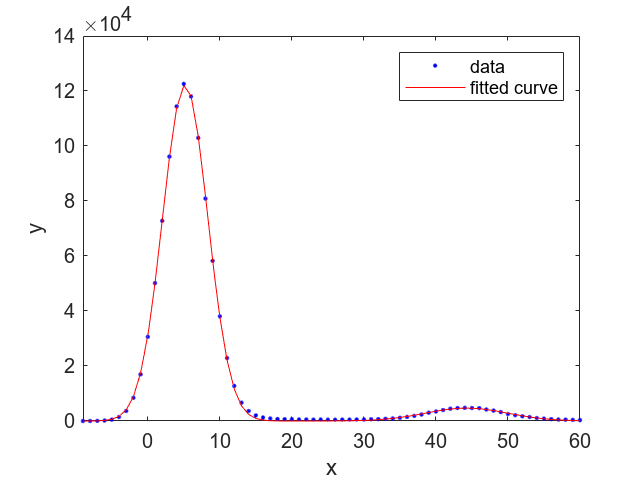


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2', 'Exclude', x>150);
plot(gaus,x,y)
xlim([-inf 60])


mean_180s = gaus.b1

mean_180s = 5.1896

sigma_180s = gaus.c1/sqrt(2)

sigma_180s = 3.1402


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0099

e_sigma = 0.0099

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

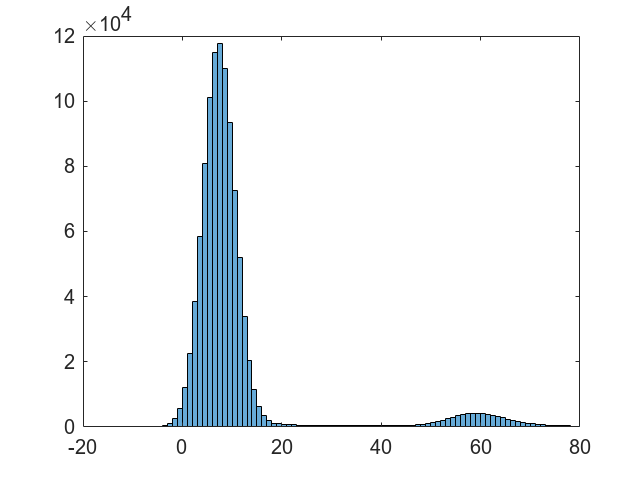

dist = histogram(image_240s, -2^15:1:2^15);
xlim([-20 80])

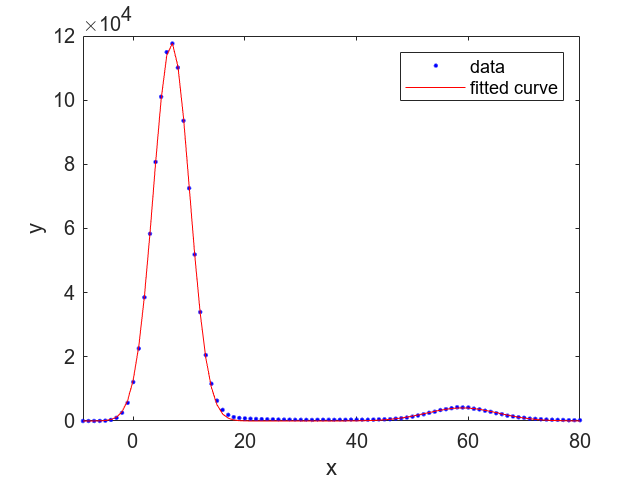


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2', 'Exclude', x>150);
plot(gaus,x,y)
xlim([-inf 80])


mean_240s = gaus.b1

mean_240s = 6.8401

sigma_240s = gaus.c1./sqrt(2)

sigma_240s = 3.2500


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0117

e_sigma = 0.0117

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

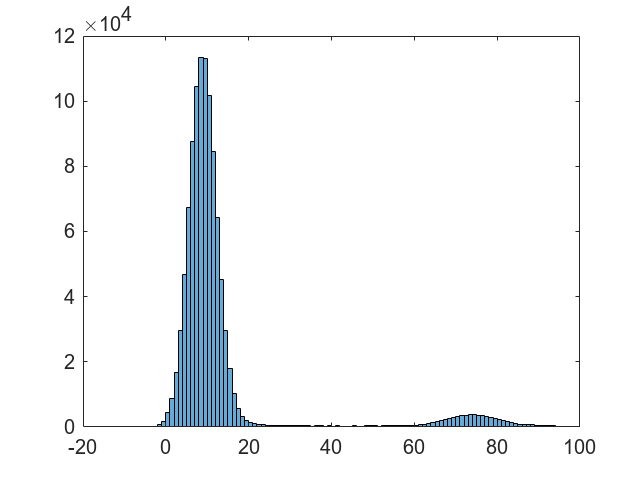

dist = histogram(image_300s, -2^15:1:2^15);
xlim([-20 100])

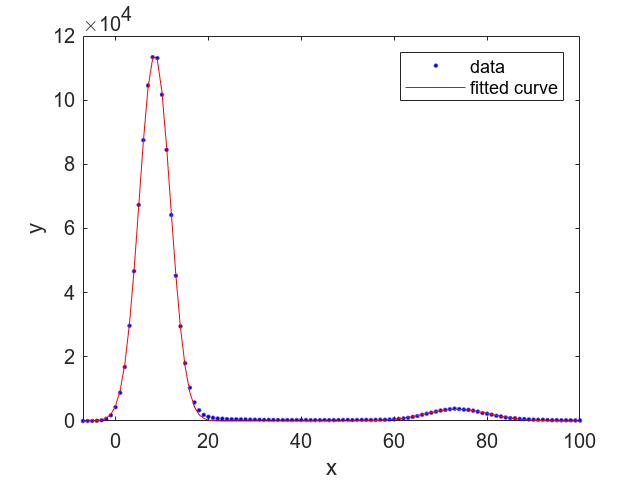


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2', 'Exclude', x>200);
plot(gaus,x,y)
xlim([-inf 100])


mean_300s = gaus.b1

mean_300s = 8.4532

sigma_300s = gaus.c1/sqrt(2)

sigma_300s = 3.3465


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0114

e_sigma = 0.0114

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

mean = [mean_1s; mean_10s; mean_60s; mean_120s; mean_180s; mean_240s; mean_300s]*3.35;
error_mean = error_mean*3.35;

sigmas = [sigma_1s; sigma_10s; sigma_60s; sigma_120s; sigma_180s; sigma_240s; sigma_300s]*3.35;
error_sigma = error_sigma*3.35;

weight = 1./sqrt(error_mean);
time = [1; 10; 60; 120; 180; 240; 300];

lin = fit(time, mean, 'poly1', 'Weights', weight);

offset = lin.p2

offset = 0.3147

ci = confint(lin);
error_offset = (ci(2,2)-ci(1,2))/2

error_offset = 0.2213

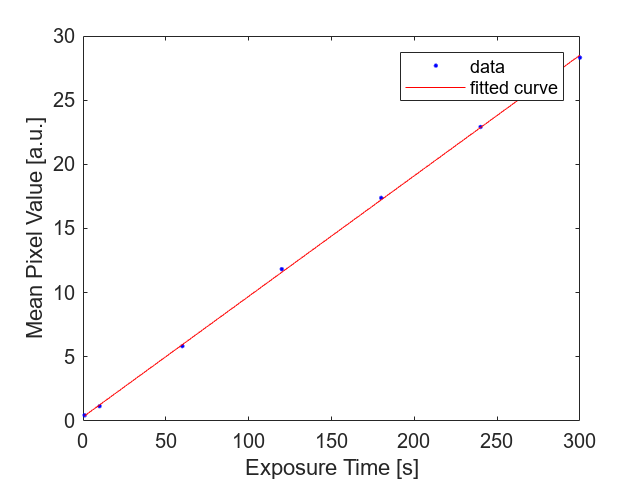


plot(lin, time, mean)
xlabel("Exposure Time [s]")
ylabel("Mean Pixel Value [a.u.]")

mean_corrected = mean - offset

mean_corrected =     0.1342
    0.8440
    5.5239
   11.5176
   17.0706
   22.5997
   28.0035


error_meancorr = sqrt(error_mean.^2 + error_offset^2)

error_meancorr =     0.2215
    0.2220
    0.2214
    0.2226
    0.2237
    0.2247
    0.2245



T_noise_1 = real(sqrt(mean_corrected))

T_noise_1 =     0.3663
    0.9187
    2.3503
    3.3938
    4.1317
    4.7539
    5.2918


error_T1 = error_meancorr./(2*sqrt(mean_corrected))

error_T1 =     0.3023
    0.1208
    0.0471
    0.0328
    0.0271
    0.0236
    0.0212


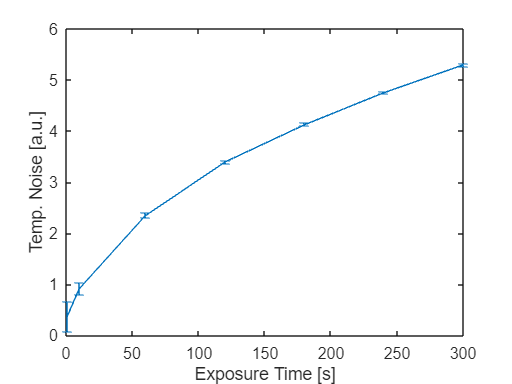


errorbar(time, T_noise_1, error_T1)
xlabel("Exposure Time [s]")
ylabel("Temp. Noise [a.u.]")

RO_noise_1 = double(imread("noise25deg_1e-05s_1_X1.tif"));
RO_noise_2 = double(imread("noise25deg_1e-05s_2_X1.tif"));

diff_image = RO_noise_2-RO_noise_1;

sigma_RO = std2(diff_image)*3.35

sigma_RO = 9.4270

RO_noise = sigma_RO/sqrt(2)

RO_noise = 6.6659


n = numel(diff_image);
RO_error = RO_noise/(sqrt(2*(n-1))*sqrt(2))

RO_error = 0.0033

T_noise_2 = sqrt(sigmas.^2 - 2*RO_noise^2)

T_noise_2 =     0.6722
    2.2642
    2.6861
    3.8675
    4.6687
    5.4468
    6.0675


error_T2 = sqrt(((2*sigmas.*error_sigma)./(2*sqrt(sigmas.^2-2*RO_noise.^2))).^2+(-((4*RO_noise)./(2*sqrt(sigmas.^2-2*RO_noise.^2)).*RO_error).^2))

error_T2 =     0.1131
    0.0755
    0.0268
    0.0642
    0.0739
    0.0778
    0.0700


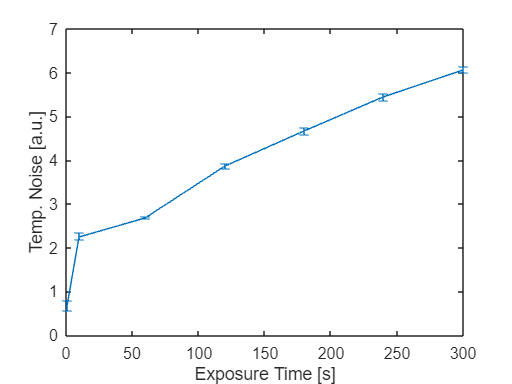


errorbar(time, T_noise_2,  error_T2)
xlabel("Exposure Time [s]")
ylabel("Temp. Noise [a.u.]")

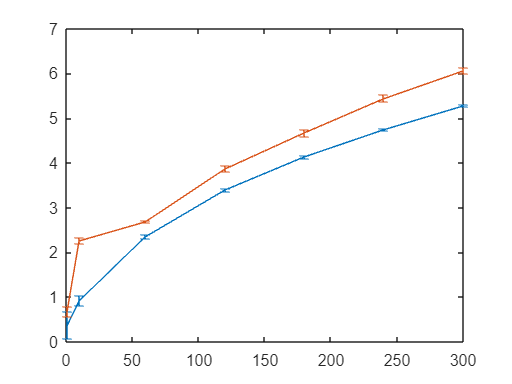

errorbar(time, T_noise_1, error_T1)
hold on
errorbar(time, T_noise_2,  error_T2)
hold off

(T_noise_1./T_noise_2)

ans =     0.5450
    0.4057
    0.8750
    0.8775
    0.8850
    0.8728
    0.8722
